# Polígono de Área Máxima

**Proyecto Ⅱ : Solución por puntos interiores.**

**Optimización Numérica**

**ITAM**

Integrantes:

- Luis Felipe Castro Corrales            181417

- Natalia Hernández Cornejo            183420

- Dara Ximena Meneses Acosta       190689

En este proyecto, utilizaremos el método de puntos interiores para obtener el polígono de $n_v$ vértices y de diametro menor o igual a uno de área máxima.

Fijamos el último vértice al origen, es decir $v_n = (0,\pi)$. Así, consideramos $n = n_v-1$ como el número de vértices sin fijar y llegamos a que el problema a minimizar es

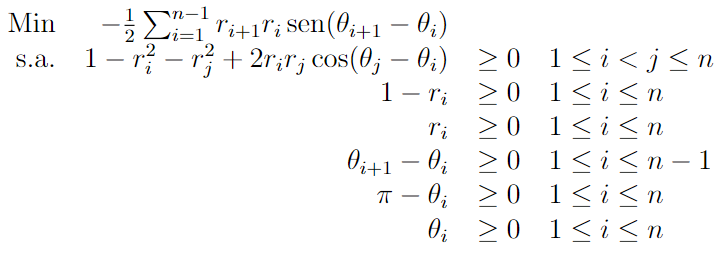

% Ejecutar esta línea para limpiar el espacio de trabajo.
clear; close all; clc;

A continuación mostraremos los polígonos obtenidos a partir de nuestra función *intpoint2 *y con el punto inicial obtenido a través de la función *pInicial*. Graficaremos todos los polígonos, y desplegaremos las iteraciones, el tiempo de CPU y el área máxima del polígono para cada número de vértices. 

% n es el números de vértices distintos del origen
hold on
for n = 2:10
    x0 = pInicial(n);
    fname = 'funobj';
    gname = 'funres';
    disp(['Polígono de ', num2str(n+1), ' lados.'])

    startTime = cputime;
    [x,mu,iter] = intpoint2(fname,gname,x0);
    total_time = cputime - startTime;
    
    r = [0 ; x(1:2:2*n-1)];
    theta = [pi; x(2:2:2*n)];
    
    % transformación a coordenadas cartesianas
    [x,y] = pol2cart(theta,r);
    
    pgon = polyshape(x,y);
    
    fprintf('Iteraciones: %2.0f \nTiempo de CPU: %2.8f segundos \nÁrea maximizada: %2.8f \n\n\n\n', iter, total_time, area(pgon))

    %Graficar polígono
    txt = ['P de ',num2str(n+1),' lados'];
    plot(pgon,'DisplayName',txt)
    
end

Polígono de 3 lados.


Iteraciones: 20 
Tiempo de CPU: 0.00000000 segundos 
Área maximizada: 0.43300886 





Polígono de 4 lados.


Iteraciones: 20 
Tiempo de CPU: 0.01000000 segundos 
Área maximizada: 0.49999744 





Polígono de 5 lados.


Iteraciones: 20 
Tiempo de CPU: 0.01000000 segundos 
Área maximizada: 0.65715748 





Polígono de 6 lados.


Iteraciones: 25 
Tiempo de CPU: 0.01000000 segundos 
Área maximizada: 0.67498100 





Polígono de 7 lados.


Iteraciones: 24 
Tiempo de CPU: 0.01000000 segundos 
Área maximizada: 0.71974037 





Polígono de 8 lados.


Iteraciones: 48 
Tiempo de CPU: 0.03000000 segundos 
Área maximizada: 0.72686848 





Polígono de 9 lados.


Iteraciones: 45 
Tiempo de CPU: 0.32000000 segundos 
Área maximizada: 0.74561923 





Polígono de 10 lados.


Iteraciones: 49 
Tiempo de CPU: 0.46000000 segundos 
Área maximizada: 0.73712161 





Polígono de 11 lados.


Iteraciones: 61 
Tiempo de CPU: 0.65000000 segundos 
Área maximizada: 0.75238518 





title("Polígonos")
xlim([-0.6 1.5])
ylim([0 1.5])
legend show
hold off

Elegimos la función *pInicial *para obtener el punto inicial ya que observamos un buen desempeño del método con este. *pInicial* regresa un polígono en forma de abaníco donde todos los radios son iguales. Más aún, también probamos el método con un polígono regular como punto inicial. Para un número pequeño de vértices, el resultado era igual. Sin embargo, para mayor número de vértices,  tener un polígono regular como punto inicial fue peor en términos de área que usar el punto inicial tipo abanico. A continuación mostramos la comparación entre los dos tipos de punto inicial. 

% n es el números de vértices distintos del origen
hold on
n = 10;
x0 = pInicial(n);
x1 = polRegular(n);
fname = 'funobj';
gname = 'funres';
disp(['Polígono de ', num2str(n+1), ' lados.'])

Polígono de 11 lados.



startTime = cputime;
[x1,mu1,iter1] = intpoint2(fname,gname,x0);
total_time1 = cputime - startTime;

startTime = cputime;
[x2,mu2,iter2] = intpoint2(fname,gname,x1);
total_time2 = cputime - startTime;
    
r1 = [0 ; x1(1:2:2*n-1)];
theta1 = [pi; x1(2:2:2*n)];
r2 = [0 ; x2(1:2:2*n-1)];
theta2 = [pi; x2(2:2:2*n)];
    
% transformación a coordenadas cartesianas
[x1,y1] = pol2cart(theta1,r1);
[x2,y2] = pol2cart(theta2,r2);
    
pgon1 = polyshape(x1,y1);
pgon2 = polyshape(x2,y2);

    
fprintf('Punto inicial abanico\nIteraciones: %2.0f \nTiempo de CPU: %2.8f segundos \nÁrea maximizada: %2.8f \n\n\n\n', iter1, total_time1, area(pgon1))

Punto inicial abanico
Iteraciones: 61 
Tiempo de CPU: 0.65000000 segundos 
Área maximizada: 0.75238518 





fprintf('Punto inicial polígono regular\nIteraciones: %2.0f \nTiempo de CPU: %2.8f segundos \nÁrea maximizada: %2.8f \n\n\n\n', iter2, total_time2, area(pgon2))

Punto inicial polígono regular
Iteraciones: 38 
Tiempo de CPU: 0.42000000 segundos 
Área maximizada: 0.72686848 






%Graficar polígono
txt = ['P de ',num2str(n+1),' lados'];
plot(pgon1,'DisplayName',txt)
plot(pgon2,'DisplayName',txt)

title("Polígonos")
xlim([-0.6 1.5])
ylim([0 1.5])
legend show
hold off